# 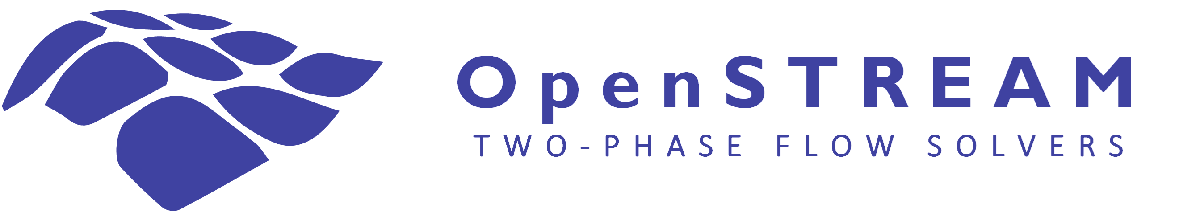

# NURETH21: OpenSTREAM: An Open-Source Platform for Two-Phase Flow Modeling and Simulation

Companion Live Script for:

[ J.-M. Le Corre, J. Chan, E. Walter, E. T. Hurlburt, and R. W. Morse, “OpenSTREAM: An open-source platform for two-phase flow modeling and simulation,” *21st International Topical Meeting on Nuclear Reactor Thermal Hydraulics* (NURETH-21), Busan, Korea, August 31 to September 5, 2025.](https://openstream.readthedocs.io/en/latest/_static/publications/LeCorre2025OpenSTREAM.pdf)

This Live Script is a reproducible computational companion to the NURETH-21 publication. It combines explanatory text, model selections, executable OpenSTREAM calculations, figures, convergence information, and interpretation in a single interactive document.

The workflow reproduces the principal OpenSTREAM calculations associated with Figures 3, 4, 6, and 7 of the publication. Each section explains the purpose of the calculation, the selected models and numerical settings, the quantities shown in the resulting figures, and the principal conclusions.

The companion focuses on the calculations needed to illustrate the published figures and conclusions. It does not include all cases, closure-model development, sensitivity studies, or numerical investigations performed during the underlying research.

**Scope and paper mapping**

- Figure 3 compares the mixture, two-fluid, three-field, and four-field frameworks.

- Figure 4 compares film characteristics predicted by the three-field and four-field frameworks.

- Figure 6 validates fully developed base-film and disturbance-wave properties using Wurtz1978.

- Figure 7 validates developing disturbance-wave behavior using Sawai1989.

- Figure 5 is not generated because the original project does not include the TRACE reference results required for a complete reproduction.

*Note: This file is designed for use with output displayed inline (View > Output Inline) in the MATLAB Live Editor. *

## 1. Setup

The relative paths assume execution from openstream-database/projects. 

NOTE: The validation case sets use *parfor*, as in the original project, and require Parallel Computing Toolbox. Users without that toolbox may replace *parfor* with *for* without changing the calculations.

% Clear the existing workspace and close open figures.
clearvars
close all

% Add OpenSTREAM-database and OpenSTREAM to the MATLAB search path.
addpath('..')
addpath(fullfile('..','..','openstream'))

% Define the common file-generation and solver-output options.
inputSetOpts = {'overwriteSessionFiles',true,'LOGMODE','BOTH'};
saveResultsToFile = false;

## 2. Demonstration case: four solver frameworks

The common boiling-water case models a 5.5 m tube with a uniformly heated 3.5 m section followed by a 2 m adiabatic section. The applied power is close to critical power. The film models therefore approach complete dryout near the end of the heated section, while the adiabatic extension exposes redistribution toward hydrodynamic equilibrium.

### 2.1 Lightweight in-memory dataset

No XML or JSON source file is required. A one-row table is passed directly to lightweight Dataset objects, demonstrating how OpenSTREAM-database supports in-memory workflows for publication cases, examples, and exploratory calculations. The field names are self-explanatory, and all numerical values use SI units, with temperatures expressed in kelvin.

% Define the case geometry, boundary conditions, and wall-power distribution.
entryData = table;
entryData.Pressure      = 6.0e6;
entryData.MassFlow      = 0.07;
entryData.InletEnthalpy = 1.1394e6;
entryData.Power         = 87.5e3;
entryData.WallMesh      = [1.75 1.75 2.0];
entryData.WallPower     = [1.0 1.0 0.0];
entryData.Perimeter     = 0.0276;
entryData.Area          = 6.0821e-5;
entryData.Length        = 5.5;
entryData.Fluid         = 'water';

% Create an independent lightweight dataset object for each solver framework.
mixture   = Dataset(1,'isLightWeight',true,'lightWeightEntryData',entryData);
twofluid   = Dataset(1,'isLightWeight',true,'lightWeightEntryData',entryData);
threefield = Dataset(1,'isLightWeight',true,'lightWeightEntryData',entryData);
fourfield  = Dataset(1,'isLightWeight',true,'lightWeightEntryData',entryData);

% Initialize the common input options and select the axial interpolation method.
opts = mixture.inputOptions();
opts.options.AXIALINTERP = 'NEXT';

The input-option structure is updated progressively. Each multi-field calculation therefore retains the previously selected common models unless a value is explicitly replaced in the corresponding section.

### 2.2 Mixture solution

The homogeneous-equilibrium mixture solution provides the system-level reference and will be used to initialize the remaining multi-field solvers. It does not resolve separate phase temperatures or individual liquid fields.

% Generate the input files and run the mixture-solver calculation.
mixture.makeInputFiles(inputOptions=opts, ioDirectory="NURETH21/Mixture");
mixture.runCase('Mixture','inputSetOpts',inputSetOpts, ...
    'saveResultsToFile',saveResultsToFile);

### 2.3 Two-fluid solution

The two-fluid calculation resolves separate liquid and vapor mass, momentum, and energy equations. The interfacial relaxation model permits thermal non-equilibrium.

% Configure the two-fluid physical and momentum models.
opts.model.INTNU        = 'RELAXATION';
opts.model.RELAXX       = [-0.5 1.0];
opts.model.RELAXCONDT   = [0.5 0.5 0.01];
opts.model.MOMENTLIQUID = 'FULL';
opts.model.MOMENTGAS    = 'FULL';
opts.model.DROPDRAG     = 'VISCOUS';

% Generate the input files and run the two-fluid calculation.
twofluid.makeInputFiles(inputOptions=opts, ioDirectory="NURETH21/Twofluid");
twofluid.runCase('TwoFluid','inputSetOpts',inputSetOpts, ...
    'saveResultsToFile',saveResultsToFile);

### 2.4 Three-field solution

The three-field model separates liquid film and entrained droplets in annular flow. The solver allows film depletion, droplet transport, and the approach to dryout to be followed explicitly.

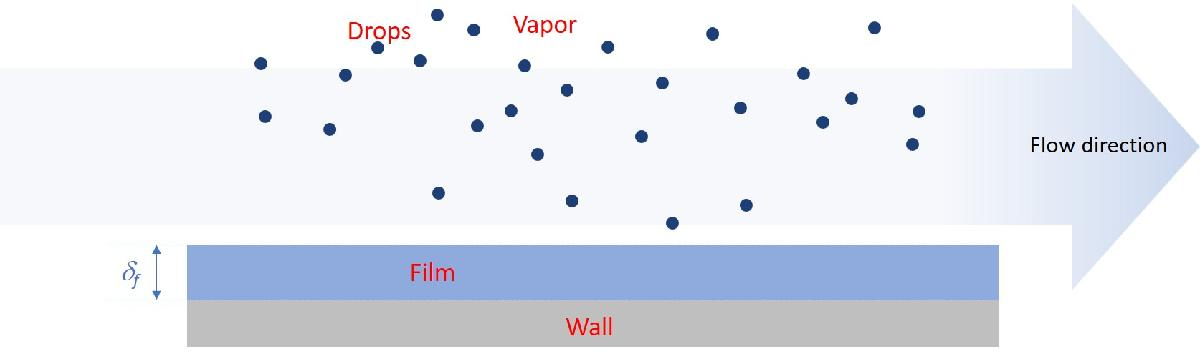

% Configure the three-field physical and momentum models.
opts.model.MOMENTFILM = 'FULL';
opts.model.MOMENTDROP = 'FULL';
opts.model.DROPDIAM   = 1.0e-3;

% Generate the input files and run the three-field calculation.
threefield.makeInputFiles(inputOptions=opts, ioDirectory="NURETH21/Threefield");
threefield.runCase('ThreeField','inputSetOpts',inputSetOpts, ...
    'saveResultsToFile',saveResultsToFile);

### 2.5 Four-field solution

The four-field model further separates the liquid film into a continuous base film and disturbance waves. It explicitly calculates the liquid mass transported by the waves, together with their amplitude, velocity, and nonequilibrium frequency development.

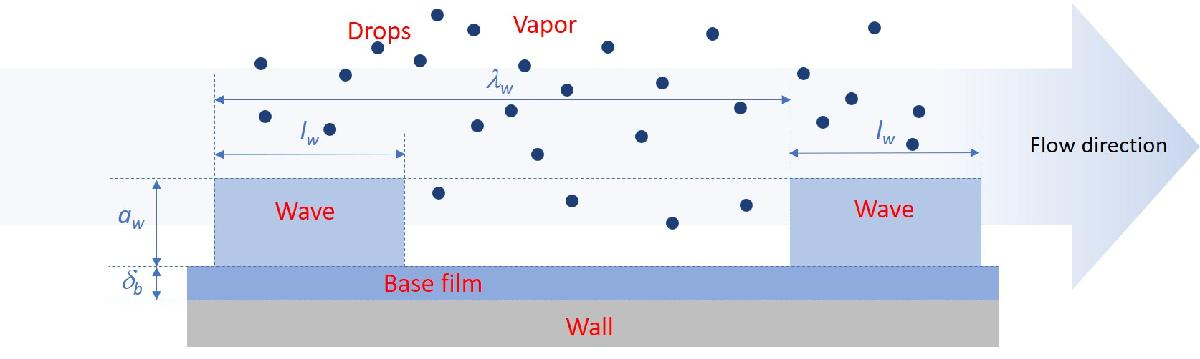

% Configure the four-field base-film and disturbance-wave models.
opts.model.MOMENTBASE   = 'FULLNOP';
opts.model.MOMENTWAVE   = 'FULL';
opts.model.WAVEBASEINT  = 'VAPORSHEARDROPMASS';
opts.model.OAFFILMSPLIT = 'RATIO';
opts.model.OAFBASERATIO = 0.3;
opts.model.BASEEQTHICK  = 'YPLUS';

% Generate the input files and run the four-field calculation.
fourfield.makeInputFiles(inputOptions=opts, ioDirectory="NURETH21/Fourfield");
fourfield.runCase('FourField','inputSetOpts',inputSetOpts, ...
    'saveResultsToFile',saveResultsToFile);

### 2.6 Convergence checks

mixture.checkConvergence();
twofluid.checkConvergence();
threefield.checkConvergence();
fourfield.checkConvergence();

### 2.7 Figures

makeFrameworkFigure(mixture,twofluid,threefield,fourfield)
makeAnnularFlowFigure(mixture,twofluid,threefield,fourfield)

The figures show consistent overall behavior across the four frameworks. The two-fluid solution resolves phase non-equilibrium, the three-field solution predicts film depletion toward dryout, and the four-field solution shows that disturbance waves carry most of the film liquid. In the adiabatic section, liquid redistributes toward the film and wave characteristics relax toward equilibrium.

## 3. Fully developed annular flow: Wurtz1978

Figure 6 validates equilibrium four-field annular-flow closure relations against the long, adiabatic TS 20 pipe measurements. The comparisons use base-film thickness, wave velocity, and wave number density over selected pressure, mass-flux, and quality ranges.

The film-entrainment model (OKAWACOEFS) uses the coefficient applied in the original NURETH-21 workflow. This reduced coefficient improves consistency with the measured film-flow data and is therefore an integral part of the reproduced model configuration.

% Initialize the Wurtz1978 dataset and configure the four-field models.
clear wurtz
solver = 'FourField';
alldata = Wurtz1978.Wurtz1978();
opts = alldata.inputOptions();
opts.model.VOID         = 'BESTION';
opts.model.OAFENTRAINED = 'EQUILIBRIUM';
opts.model.DEPOSITION   = 'OKAWA';
opts.model.ENTRAINMENT  = 'OKAWAGEN';
opts.model.OKAWACOEFS   = [320 0.111 3.50e-4 1];
opts.model.OAFFILMSPLIT = 'EQUILIBRIUM';
opts.model.MOMENTBASE   = 'FULLNOP';
opts.model.MOMENTWAVE   = 'FULL';
opts.model.VAPORFRIC    = 'CONST';
opts.model.VAPORFRICCST = 0.005;
opts.model.WAVEBASEINT  = 'VAPORSHEAR';

% Select the fully developed annular-flow cases from the TS 20 test section.
runIndexes = find(ismember(alldata.dataset.TestName','TS 20'));

% Generate the input files and run the selected cases in parallel.
parfor i = 1:numel(runIndexes)
    wurtz(i) = Wurtz1978.Wurtz1978(runIndexes(i), ...
        'isLightWeight',true, ...
        'lightWeightEntryData',alldata.dataset(runIndexes(i),:));
    wurtz(i).makeInputFiles(inputOptions=opts, ioDirectory="NURETH21/Wurtz");
    wurtz(i).runCase(solver,'inputSetOpts',inputSetOpts, ...
        'saveResultsToFile',saveResultsToFile);
end


% Convergence checks
wurtz.checkConvergence();


% Figures
wurtz.plotResults('basethickness',solver)
wurtz.plotResults('wavevelocity',solver)
wurtz.plotResults('wavenumberdensity',solver)

The comparisons assess equilibrium four-field closure relations for base-film thickness, wave velocity, and wave number density. The reduced entrainment coefficient specified through OKAWACOEFS is part of this model configuration and should be reported whenever these results are reproduced.

## 4. Developing annular flow: Sawai1989

Figure 7 follows disturbance-wave development through a heated section and recovery in a downstream unheated section. Four cases at two outlet-quality levels and two mass fluxes test whether the wave-number-density transport and relaxation model captures spatial non-equilibrium.

% Initialize the Sawai1989 dataset and configure the four-field models.
clear sawai
solver = 'FourField';
alldata = Sawai1989.Sawai1989();
opts = alldata.inputOptions();
opts.model.THERMALNONEQ    = 'EPRI';
opts.model.VOID            = 'EPRI';
opts.model.TPFM            = 'EPRI';
opts.model.OAFENTRAINED    = 'EQUILIBRIUM';
opts.model.DEPOSITION      = 'OKAWA';
opts.model.ENTRAINMENT     = 'OKAWA2003';
opts.model.OAFFILMSPLIT    = 'EQUILIBRIUM';
opts.model.MOMENTWAVE      = 'FULL';
opts.model.MOMENTBASE      = 'FULLNOP';
opts.model.VAPORFRIC       = 'CONST';
opts.model.VAPORFRICCST    = 0.005;
opts.model.WAVEMIXCOEF     = 2;
opts.model.THINFILMTHICK   = 1.0e-4;
opts.model.THINWAVETHICK   = 1.0e-5;
opts.model.SHAPEFACTORCOEF = [1.325e5 2 1 0];
opts.model.EQSTROUHAL      = 'SAWAI';
opts.model.RELAXTB         = 0.5;
opts.model.WAVEFREQUENCY   = 'RELAXATION';
opts.model.RELAXTW         = 0.1;

% Select the cases used to validate disturbance-wave development.
runIndexes = [1 2 5 6];

% Generate the input files and run the selected cases in parallel.
parfor i = 1:numel(runIndexes)
    sawai(i) = Sawai1989.Sawai1989(runIndexes(i), ...
        'isLightWeight',true, ...
        'lightWeightEntryData',alldata.dataset(runIndexes(i),:));
    sawai(i).makeInputFiles(inputOptions=opts, ioDirectory="NURETH21/Saway");
    sawai(i).runCase(solver,'inputSetOpts',inputSetOpts, ...
        'saveResultsToFile',saveResultsToFile);
end


% Convergence checks
sawai.checkConvergence();


% Figures
sawai.plotResults(solver)

Measured and predicted wave velocity and wave period are compared through the heated and adiabatic regions. The equilibrium wave period is included as a reference. The paper concludes that the selected 0.1 s relaxation time reproduces the measured trends and shows why an algebraic equilibrium-frequency model is insufficient for developing annular flow.

## 5. Summary of reproduced findings

The demonstration case confirms consistent system-level trends across the four solver frameworks while progressively resolving phase, film, droplet, base-film, and disturbance-wave behavior. The Wurtz calculations assess equilibrium four-field closure relations against fully developed annular-flow measurements. The Sawai calculations assess the spatial relaxation of disturbance-wave properties under developing conditions.

Together, these calculations reproduce the principal OpenSTREAM results presented in the NURETH-21 publication.

## 6. Local plotting functions

function makeFrameworkFigure(mixture,twofluid,threefield,fourfield)
% MAKEFRAMEWORKFIGURE Compare the four OpenSTREAM solver frameworks.
%
% The figure compares wall heat flux, liquid-field mass flow rates, and
% void fraction or equilibrium quality for the common demonstration case.

% Retrieve the calculated fields from each solver framework.
mix=mixture.results.mixture; liquid=twofluid.results.liquid; vapor=twofluid.results.vapor;
film=threefield.results.film; drop=threefield.results.drop;
base=fourfield.results.film.base; wave=fourfield.results.film.wave;

% Define the annular-flow range and common plotting properties.
k=mix.OAFIDX:mix.NZ;
colors=lines(4);
lineWidth=2;

% Create the framework-comparison figure.
figure('Name','Framework comparison: heat flux, liquid flow, and void', ...
    'Units','normalized', 'Position',[0.05 0.20 0.90 0.55]);
tiledlayout(1,3,'TileSpacing','compact','Padding','compact')

% Plot the imposed axial heat-flux distribution.
nexttile; hold on; grid on;
plot(mix.Z,mix.HFLUX,'LineWidth',lineWidth);
xlabel('Elevation [m]'); ylabel('Heat flux [W/m^2]')

% Compare the calculated liquid-field mass flow rates.
nexttile; hold on; grid on
plot(mix.Z,mix.liquid.W,'-','Color',colors(1,:),'LineWidth',lineWidth,'DisplayName','Mixture')
plot(liquid.Z,liquid.W,'-','Color',colors(2,:),'LineWidth',lineWidth,'DisplayName','Two-fluid')
plot(film.Z(k),film.W(k),'-','Color',colors(3,:),'LineWidth',lineWidth,'DisplayName','Three-field film')
plot(drop.Z(k),drop.W(k),'--','Color',colors(3,:),'LineWidth',lineWidth,'DisplayName','Three-field drops')
plot(base.Z(k),base.W(k),'-','Color',colors(4,:),'LineWidth',lineWidth,'DisplayName','Four-field base')
plot(wave.Z(k),wave.W(k),'--','Color',colors(4,:),'LineWidth',lineWidth,'DisplayName','Four-field waves')
plot(mix.Z,mix.W,'k:','LineWidth',lineWidth,'DisplayName','Total'); xline(mix.OAFZ,'r--','HandleVisibility','off');
xlabel('Elevation [m]'); ylabel('Liquid mass flow rate [kg/s]'); legend

% Compare the calculated void fractions and vapor qualities.
nexttile; hold on; grid on
plot(mix.Z,mix.VF,'-','Color',colors(1,:),'LineWidth',lineWidth,'DisplayName','Mixture void')
plot(mix.Z,mix.X,'--','Color',colors(1,:),'LineWidth',lineWidth,'DisplayName','Mixture quality')
plot(mix.Z,vapor.VF(liquid),'-','Color',colors(2,:),'LineWidth',lineWidth,'DisplayName','Two-fluid void')
plot(mix.Z,vapor.X,'--','Color',colors(2,:),'LineWidth',lineWidth,'DisplayName','Two-fluid quality')
xline(mix.OAFZ,'r--','HandleVisibility','off');
xlabel('Elevation [m]'); ylabel('Void fraction [-]'); legend
end

function makeAnnularFlowFigure(mixture,twofluid,threefield,fourfield)
% MAKEANNULARFLOWFIGURE Compare calculated annular-flow field properties.
%
% The figure compares liquid-film dimensions, field velocities, and
% disturbance-wave frequency for the common demonstration case.

% Retrieve the calculated fields from each solver framework.
mix=mixture.results.mixture;
liquid=twofluid.results.liquid;
film=threefield.results.film; drop=threefield.results.drop;
base=fourfield.results.film.base; wave=fourfield.results.film.wave;

% Define the annular-flow range and common plotting properties.
k=mix.OAFIDX:mix.NZ;
colors=lines(4);
lineWidth=2;

% Create the annular-flow comparison figure.
figure('Name','Framework comparison: annular-flow parameters', ...
    'Units','normalized', 'Position',[0.05 0.20 0.90 0.55]);
tiledlayout(1,3,'TileSpacing','compact','Padding','compact')

% Compare the calculated liquid-film transverse dimensions
nexttile; hold on; grid on
plot(film.Z(k),film.THICK(k).*1e3,'-','Color',colors(3,:),'LineWidth',lineWidth,'DisplayName','Three-field film')
plot(base.Z(k),base.THICK(k).*1e3,'-','Color',colors(4,:),'LineWidth',lineWidth,'DisplayName','Base film')
plot(wave.Z(k),wave.AMPLITUDE(k).*1e3,'--','Color',colors(4,:),'LineWidth',lineWidth,'DisplayName','Waves')
xline(mix.OAFZ,'r--','HandleVisibility','off');
xlabel('Elevation [m]'); ylabel('Film transverse dimension [mm]'); legend

% Compare the calculated phase and liquid-field velocities.
nexttile; hold on; grid on
plot(mix.Z,mix.vapor.U,'-','Color',colors(1,:),'LineWidth',lineWidth,'DisplayName','Mixture vapor')
plot(liquid.Z,liquid.U,'-','Color',colors(2,:),'LineWidth',lineWidth,'DisplayName','Two-fluid liquid')
plot(film.Z(k),film.U(k),'-','Color',colors(3,:),'LineWidth',lineWidth,'DisplayName','Three-field film')
plot(drop.Z(k),drop.U(k),'--','Color',colors(3,:),'LineWidth',lineWidth,'DisplayName','Three-field drops')
plot(base.Z(k),base.U(k),'-','Color',colors(4,:),'LineWidth',lineWidth,'DisplayName','Base film')
plot(wave.Z(k),wave.U(k),'--','Color',colors(4,:),'LineWidth',lineWidth,'DisplayName','Waves')
xline(mix.OAFZ,'r--','HandleVisibility','off');
xlabel('Elevation [m]'); ylabel('Velocity [m/s]'); legend

% Compare the nonequilibrium and local-equilibrium wave frequencies.
nexttile; hold on; grid on
plot(wave.Z(k),wave.FREQUENCY(k),'-','Color',colors(4,:),'LineWidth',lineWidth,'DisplayName','Non-equilibrium')
plot(wave.Z(k),wave.EQFREQUENCY(k),'r:','LineWidth',lineWidth,'DisplayName','Equilibrium')
xline(mix.OAFZ,'r--','HandleVisibility','off');
xlabel('Elevation [m]'); ylabel('Wave frequency [Hz]'); legend
end